# Localized Cluster Enhancement

## Introduction to TFCE

### The TFCE transformation

TFCE (threshold-free cluster enhancement) is a method developed in (Smith and Nichols, 2009) which aims to boost discoveries by aggregating information. Let $\mathcal{B}$ be the domain of interest and TFCE transforms a test-statistic $T: \mathcal{B} \rightarrow \mathbb{R}$ into:

 
$$S_v(T) = \int_{h_0}^{T(v)} h^H e_v(h,T)^E \mathrm{d} h,
$$


at each $v \in \mathcal{B}$. To understand the TFCE integral, consider the following plot.

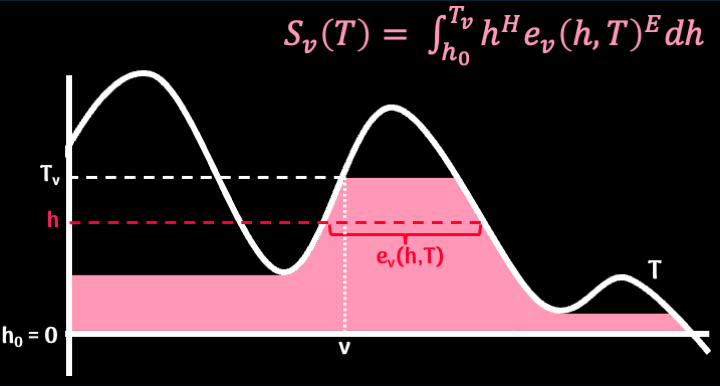

The highlighted pink area indicates the parts of the graph below the curve which are taken into account when calculating the TFCE statistic at a given $v \in \mathcal{B}$. Note that the values can depend on parts of the test-statistic relatively far away from $v$. 

We can illustrate this transformation with a simple 2D example. 

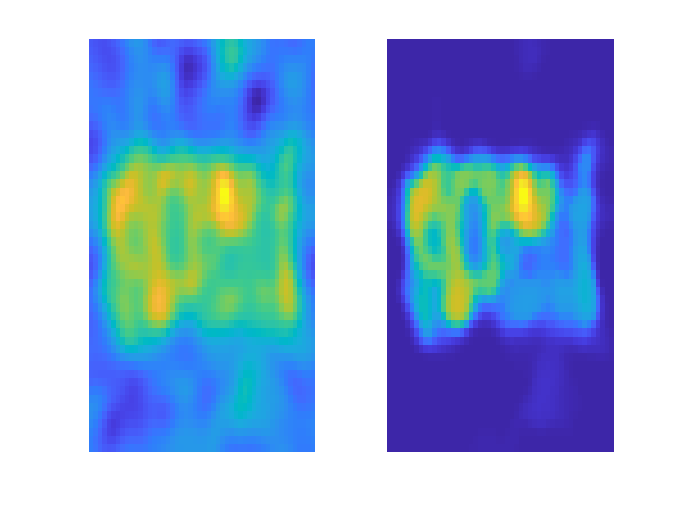

rng(1)
connectivity_criterion = 8; H = 2; E = 0.5; dim = [50,50];
nsubj = 50; FWHM = 5;
Sig = 0.1*square_signal(dim, 10, {[25,15], [25,36]} );
%Sig = 0.1*square_signal(dim, 10, {[25,14], [25,36]} );
data = randn([dim, nsubj]) + Sig;
data = fast_conv(data, FWHM, 2);
tstat_orig = mvtstat(data);
tfce_tstat = tfce(tstat_orig, H, E, connectivity_criterion);
subplot(1,2,1); imagesc(tstat_orig); axis off
subplot(1,2,2); imagesc(tfce_tstat); axis off

The TFCE transformation does a good job of separating out the signal, visually making it easier to differentiate the signal from the noise.

figure; set(gcf,'Visible','on')
subplot(1,2,1)
viewthresh(Sig > 0, [1,0,0], [1,1,1])

ans = ans(:,:,1) =
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1     1     1     1

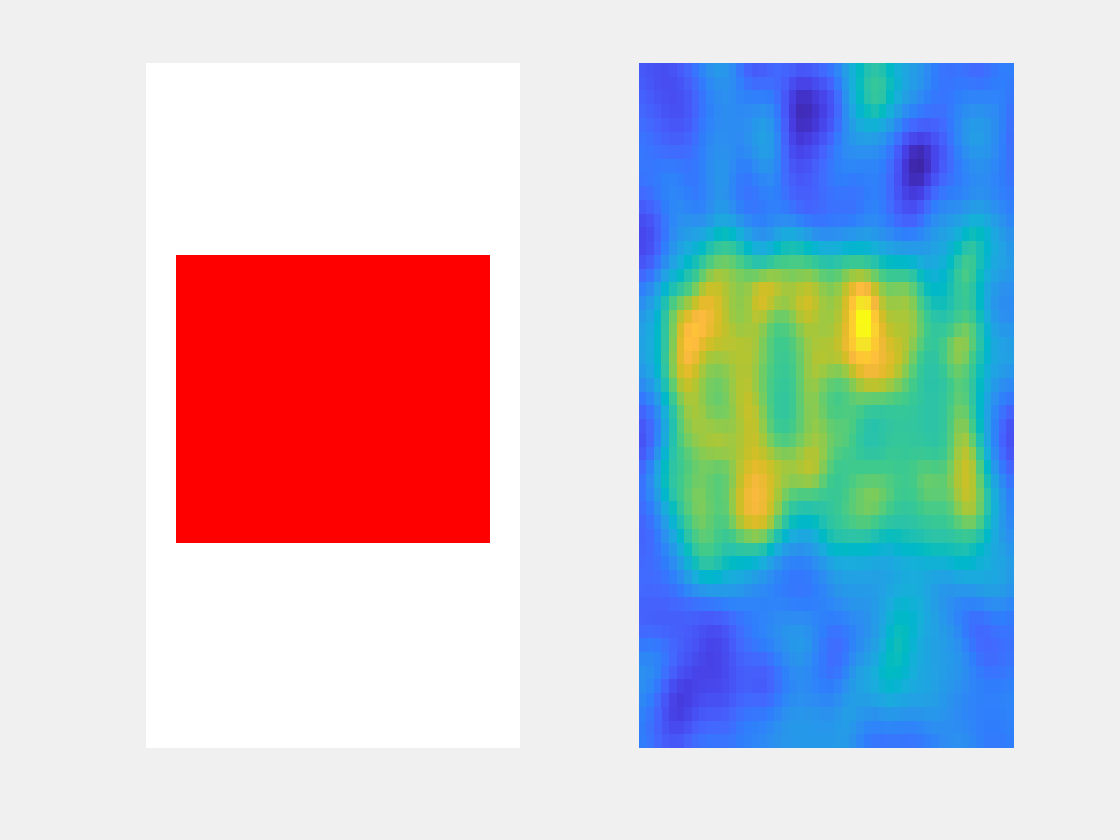

subplot(1,2,2)
imagesc(tstat_orig); axis off
saveim('signal.png')

### TFCE permutation

In order to do inference TFCE permutes the data to obtain permuted test-statistics $T_2^*, \dots, T_P^*$  and corresponding transformed TFCE test-statistics $S_2^*, \dots, S_P^*$ where $P$ is the number of permutations (taking $T_1^* = T
$ and $S_1^* = S
$). Given a level $\alpha \in (0,1)$, the standard traditional TFCE procedure obtains the $(1-\alpha)$ quantile $q$ of $\max_{v \in \mathcal{B}} S_v$ and then thresholds the original TFCE image, returning the voxels $v$ for which $S_v > q$. 

In StatBrainz this can be done using the function perm_tfce.m. This is done in the following code example. Significant voxels are shown in yellow.

figure; set(gcf,'Visible','on')
[threshold_tfce, vec_of_maxima_tfce] = perm_tfce(data, ones(dim), H, E, connectivity_criterion);

-------------------------------------------------------
tfce perm progress: 100.0


subplot(1,2,1); viewthresh(tfce_tstat > threshold_tfce, [1,0,0], [1,1,1]); title('TFCE', 'color', 'white');

threshold_cluster = perm_cluster(data, ones(dim), 2.3, connectivity_criterion);

-------------------------------------------------------
cluster perm progress: 100.0


[number_of_clusters, occurences, sizes, index_locations] = numOfConComps(tstat_orig, 2.3, connectivity_criterion);
surviving_cluster_im = cluster_im( dim, index_locations, threshold_cluster );
subplot(1,2,2); viewthresh(surviving_cluster_im, [1,1,0]); title('Cluster size inference', 'color', 'white');
fullscreen

ans =            1           1        1512         982


BigFont(25)
saveim

Importantly neither method controls voxelwise false positives as 

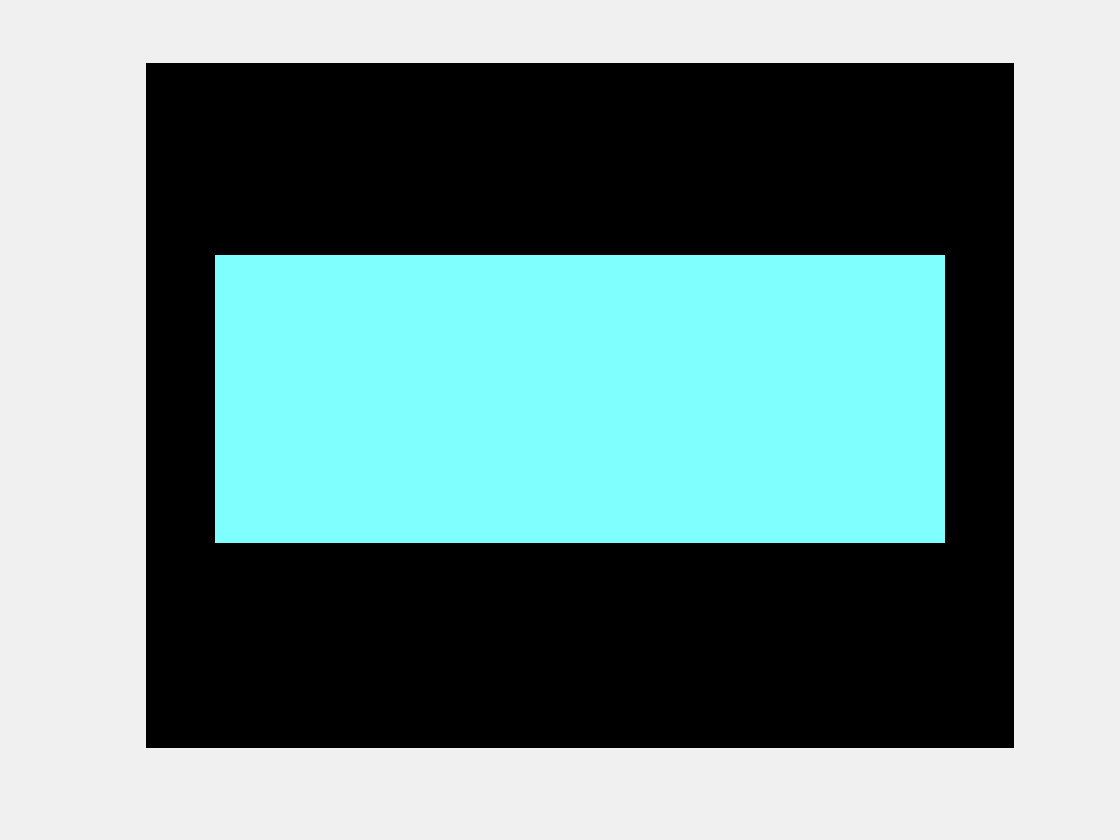

ans = ans(:,:,1) =
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0

figure; set(gcf,'Visible','on')
viewthresh(Sig > 0, [0.5,1,1])

figure; set(gcf,'Visible','on')
subplot(1,2,1); viewthresh(tfce_tstat > threshold_tfce, [0.5,1,1]); title('TFCE', 'color', 'white');
subplot(1,2,2); viewthresh(surviving_cluster_im, [1,0.5,0.5]); title('Cluster size inference', 'color', 'white');
fullscreen

ans =            1           1        1512         982


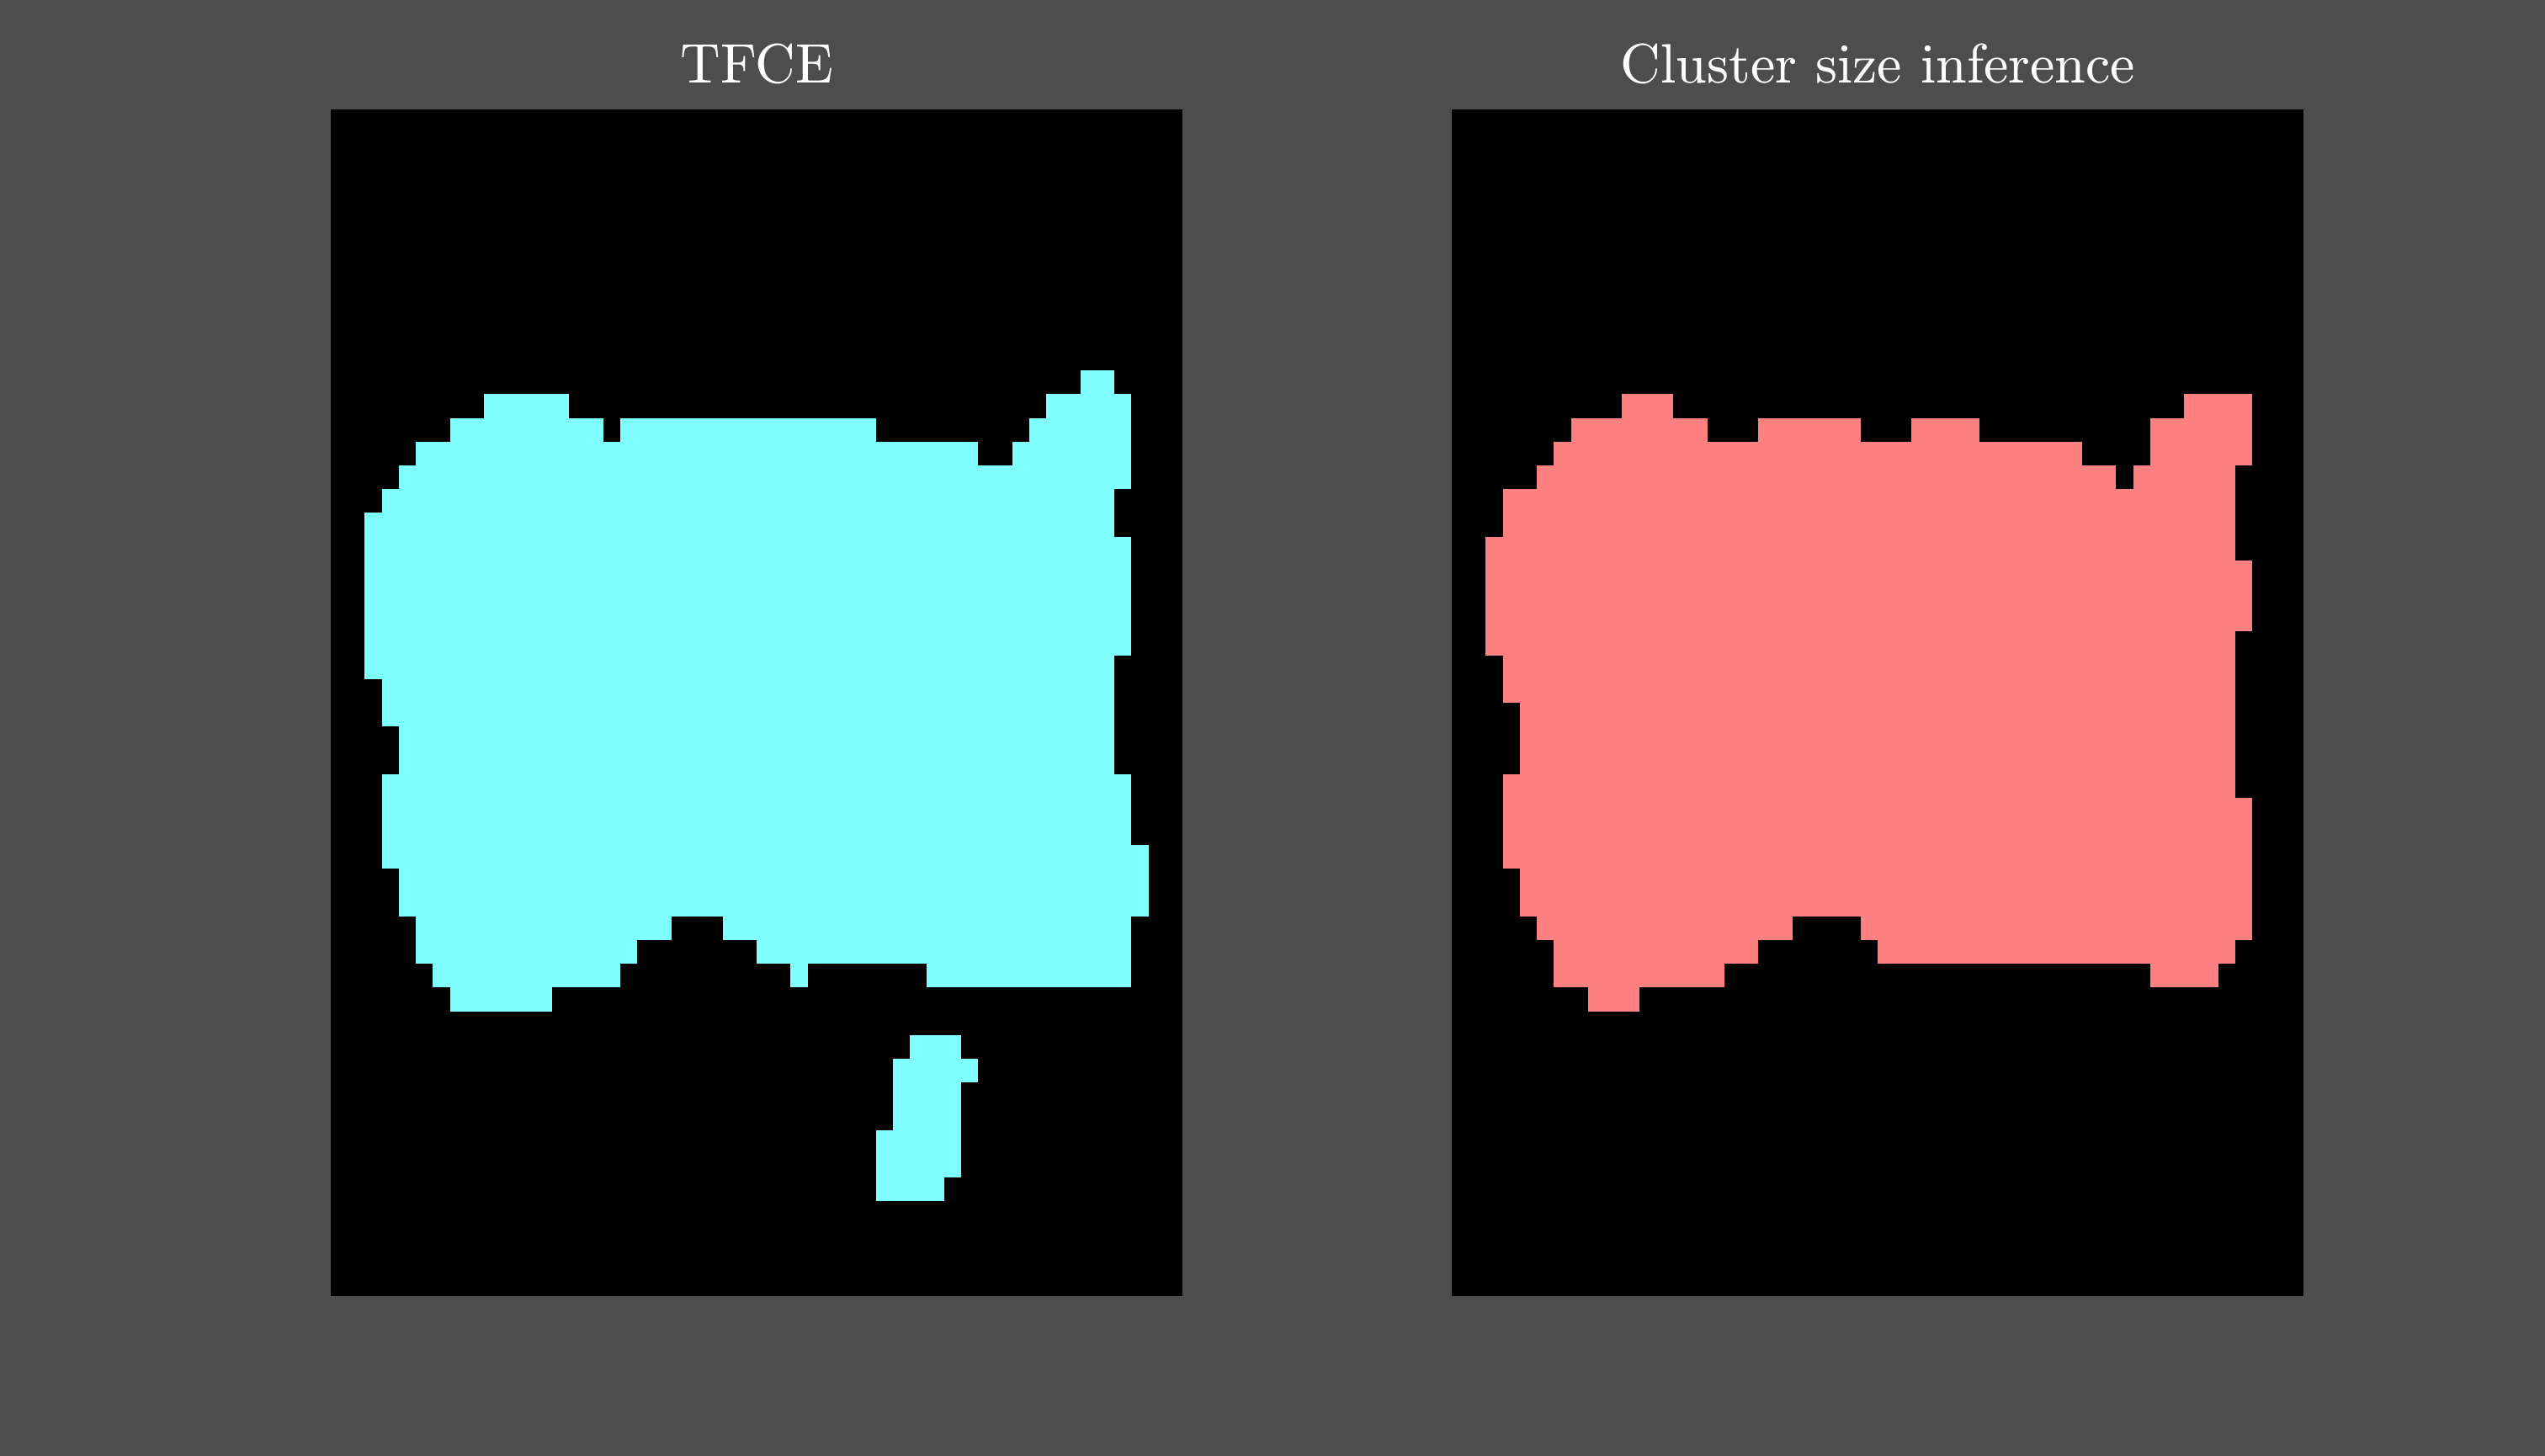

BigFont(30)
set(gcf, 'Color', [0.3,0.3,0.3]);

background = zeros([dim,3]);
imagesc(background);
hold on
frontground = surviving_cluster_im;
color = zeros([dim,3]);
color(:,:,1) = frontground;
color(:,:,2) = frontground;
imagesc(color)

color = zeros([dim,3]);
color(:,:,1) = Sig > 0;
im = imagesc(color)

im =   Image with properties:

           CData: [50×50×3 double]
    CDataMapping: 'scaled'

  Show all properties

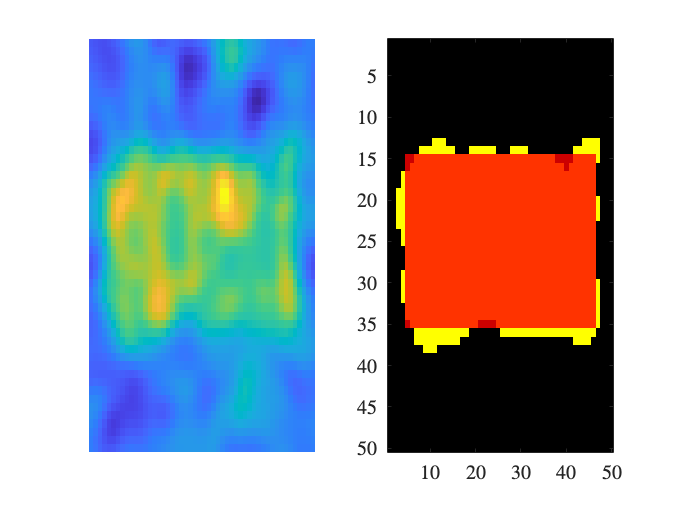

set(im,'AlphaData',0.8*(Sig > 0));


%color = ones([size(brain_mask), 3]).*outside_color;
%im2 = imagesc(color);
%set(im2,'AlphaData',1-brain_mask);
%viewdata( ones(dim), ones(dim), {surviving_cluster_im}, {'red'}, 1)
%subplot(1,2,2); viewthresh(surviving_cluster_im, [1,1,0]); title('Cluster size inference');

Moreover  TFCE finds two clusters and cluster size find just one. The smaller cluster that TFCE finds is a false positive. If you play around with the seed you can see that this doesn't always happen, however it does happen a non-trivial percent of the time. 

Unfortunately TFCE does not 

subplot(1,2,1);  viewdata( Sig > 0, brain_mask, region_masks, colors2use); title('TFCE');

## Localized Cluster Enhancement

Localized Cluster Enhancement is an improvement which retains the benefits of TFCE whilst correctly controlling flase positives and allowing for localized inference. It achieves this by embedding the original TFCE approach within a closed testing framework.

Applying LCE to the TFCE significant clusters

[number_of_tfce_clusters, ~, ~, index_locations] = numOfConComps(tfce_tstat, threshold_tfce, connectivity_criterion);
[ surviving_tfce_cluster_im, surviving_tfce_clusters, surviving_tfce_clusters_vec] = cluster_im( size(tfce_tstat), index_locations, 0.5 );

[pvals, max_tfce_within_region] = LCE(tstat_orig, surviving_tfce_clusters_vec, vec_of_maxima_tfce)

-------------------------------------------------------
Progress:  100.0


pvals =     0.0010    0.4640


max_tfce_within_region = 1.0e+03 *

    2.2545    0.0374



subplot(1,2,1); viewthresh(tfce_tstat > threshold_tfce, [0.5,1,1]); title('TFCE', 'color', 'white');
subplot(1,2,2); viewthresh(lce_cluster_im, [1,0.5,0.5]); title('LCE', 'color', 'white');
fullscreen
BigFont(30)
set(gcf, 'Color', [0.3,0.3,0.3]);

## Three dimensional brain imaging example